This section takes loads eigenvectors for Mach = 0.6

clear all;
completeName1 = 'Y:\rawdata\Sandia_cavity\SpectralConvergenceResults_Mach0.6\Phi_260.mat';
load(completeName1);

This section loads eigenvectors for Mach = 0.8

completeName2 = 'Y:\rawdata\Sandia_cavity\SpectralConvergenceResults\Phi2_280.mat';
load(completeName2);

Now we can get Phi(x,f)*Phi(x)

Phix = load('Y:\rawdata\Sandia_cavity\ConvergenceResults\Mach0.8\Phi_ensN_5000.txt');

Phi3 = Phi2(:,1,2);
Phi4 = Phix(:,1);
b1 = Phi4'*Phi3;
Phi4 = Phix(:,2);
b2 = Phi4'*Phi3;
Phi4 = Phix(:,3);
b3 = Phi4'*Phi3;
Phi4 = Phix(:,4);
b4 = Phi4'*Phi3;
Phi4 = Phix(:,5);
b5 = Phi4'*Phi3;
Phi4 = Phix(:,6);
b6 = Phi4'*Phi3;
Phi4 = Phix(:,7);
b7 = Phi4'*Phi3;
Phi4 = Phix(:,8);
b8 = Phi4'*Phi3;
Phi4 = Phix(:,9);
b9 = Phi4'*Phi3;

Compare Phi and Phi2

Phi3 = Phi(:,1:5,:);
Phi_dot(:,1) = abs(dot(Phi2(:,1,:),Phi3(:,1,:)));

for ens_num = 211:230
    uv123 = load(strcat('Y:\rawdata\Sandia_cavity\Spectral velocity data\vel_ens\Mach0.6\ens_num_',int2str(ens_num),'.txt'));
    uv11 = uv123(:,2:17:386);
    if ens_num == 1
        uv22 = uv11;
    else
        uv22 = horzcat(uv22,uv11);
    end
    
end

Get POD for mach 0.6 data

uv_6 = uv22(:,1:5000);
uv6m = mean(uv_6,2);
uv_6 = uv_6 - uv6m;
[ eigvec, eigval1, PODcoeff, Phi6 ] = POD_Snapshot( uv_6 );

Phi5 = Phi(:,1,2);

Undefined function or variable 'Phi'.

Phi7 = Phi6(:,1);
c1 = Phi5'*Phi7;
Phi7 = Phi6(:,2);
c2 = Phi5'*Phi7;
Phi7 = Phi6(:,3);
c3 = Phi5'*Phi7;
Phi7 = Phi6(:,4);
c4 = Phi5'*Phi7;
Phi7 = Phi6(:,5);
c5 = Phi5'*Phi7;
Phi7 = Phi6(:,6);
c6 = Phi5'*Phi7;
Phi7 = Phi6(:,7);
c7 = Phi5'*Phi7;
Phi7 = Phi6(:,8);
c8 = Phi5'*Phi7;
Phi7 = Phi6(:,9);
c9 = Phi5'*Phi7;

The correlation coefficient between frequency depdent POD modes and spatial POD modes help in understanding 

% Load Phi(x,f)
completeName2 = 'Y:\rawdata\Sandia_cavity\SpectralConvergenceResults\Phi3_280.mat';
load(completeName2);
% Get energy values
completeName1 = 'Y:\rawdata\Sandia_cavity\SpectralConvergenceResults\eigval_280.txt';
eig1 = load(completeName1);
[eigDec, m_index, f_index] = DecEn_eigval(eig1);
PhiDec = zeros(6360,100);
for ii = 1:100
    PhiDec(:,ii) = Phi3(:,m_index(ii),f_index(ii));
end

Now, the same thing is done for modes from the snapshot application,

% Load Phi(x)
completeName3 = 'Y:\rawdata\Sandia_cavity\ConvergenceResults\Mach0.8\Phi_ensN_5000.txt';
PhiSpat = load(completeName3);

Get the correlation coefficient,

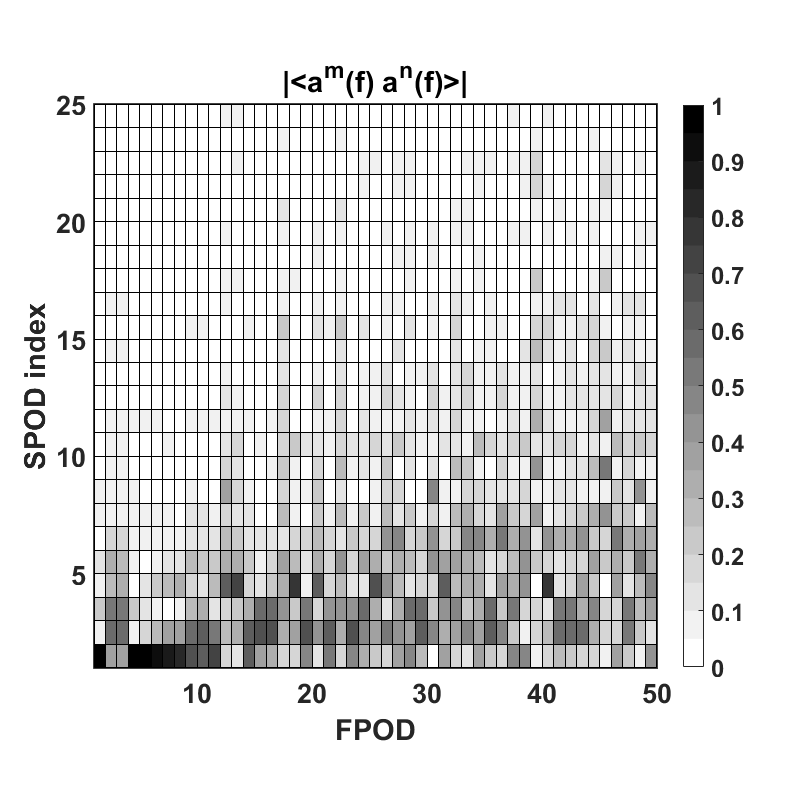

Phi_corr = PhiSpat'*PhiDec;
Phi_corr_abs = abs(Phi_corr);
figure();
c = gray(10);
c =  flipud(c);
colormap(c);
h = pcolor(Phi_corr_abs(1:100,1:100));
format_graph(1);
caxis([0 1])
colorbar;
ylabel('SPOD index','FontWeight','Bold','FontSize',38)
title('|<a^m(f) a^n(f)>|')
xlabel('FPOD','FontWeight','Bold','FontSize',38),

This section calculates the correlation coefficient from application of  SPOD vs FPOD